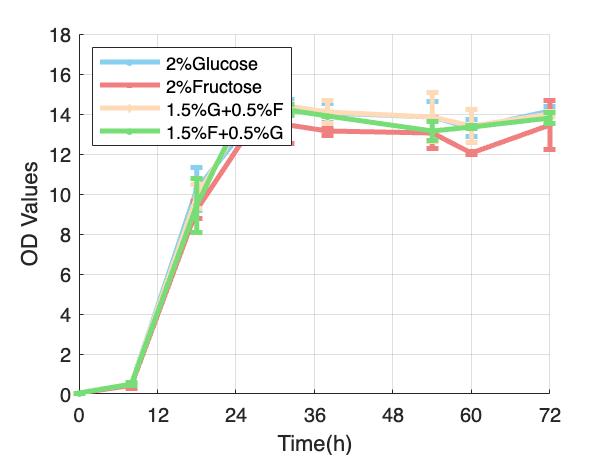

% 1. Read the Data from Excel
filename = 'WT S.B Growth Curve Data.xlsx'; % replace with your file path
[data, text] = xlsread(filename, 2); % Read from the second sheet

time = data(:, 1); % Time data from column A
conditions = data(:, 2:9); % OD values for the 8 sugar conditions

% 2. Define the Colors for Plotting
colors = {'#89CFF0', '#F08080', '#FFDAB9', '#77DD77'}; % Colors for groups A&B, C&D, E&F, G&H

% 3.1 Calculate Standard Deviations
numGroups = 4; % Since you have 8 columns and want to group every two columns
stdValues = zeros(length(time), numGroups); % Pre-allocate for efficiency

for i = 1:numGroups
    col1 = conditions(:, 2*i-1); % First column of the group
    col2 = conditions(:, 2*i);   % Second column of the group
    stdValues(:, i) = std([col1, col2], 0, 2); % Standard deviation along rows
end

% 3.2 Plot the Growth Curves with Connected Dots and Error Bars
figure;
hold on;

for i = 1:numGroups
    groupMean = mean([conditions(:, 2*i-1), conditions(:, 2*i)], 2); % Average for each time point
    errorbar(time, groupMean, stdValues(:, i), '-o', 'Color', colors{i}, 'MarkerSize', 1, 'LineWidth', 2.5);
end

% Custom legend with dummy plots
h(1) = plot(NaN,NaN, '-o', 'Color', '#89CFF0', 'MarkerSize', 1, 'LineWidth', 2.5); % dummy plot for B & C (Soft Blue)
h(2) = plot(NaN,NaN, '-s', 'Color', '#F08080', 'MarkerSize', 1, 'LineWidth', 2.5); % dummy plot for D & E (Pastel Green)
h(3) = plot(NaN,NaN, '-d', 'Color', '#FFDAB9', 'MarkerSize', 1, 'LineWidth', 2.5); % dummy plot for F & G (Pale Orange)
h(4) = plot(NaN,NaN,'-om', 'Color', '#77DD77', 'MarkerSize', 1, 'LineWidth', 2.5); % dummy plot
legendEntries = {
    [text{1, 2}]; 
    [text{1, 4}];
    [text{1, 6}];
    [text{1, 8}]
};

legend(h, legendEntries, 'Location', 'northwest');

% 4. Customize the Graph
%title('S.B Growth Curve without O2');
xlabel('Time(h)');
ylabel('OD Values');
ylim([0 18]); % Set y-axis limits from 0 to 18
grid on;

% Set x-axis limits and ticks
xlim([0 72]);
xticks(0:12:72);

% 5. Save the Graph (optional)
saveas(gcf, 'WT_S.B_growth_curve_plot_noO2.png'); % saves the graph as a PNG image